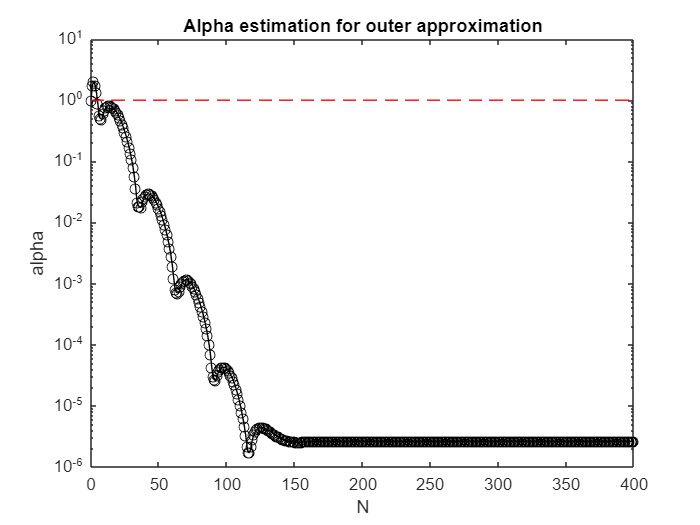

clear all
clc
%vehicle properties
vehProps.m=1550;
vehProps.Jz=2000;
vehProps.C1=2*1.6*1e3*180/pi;       % N/rad, per axle
vehProps.C2=2*.5*1e3*180/pi;        % N/rad, per axle
vehProps.CMz1=2*0.13*1e3*180/pi;    % Nm/rad, per axle
vehProps.CMz2=2*0.06*1e3*180/pi;    % Nm/rad, per axle
vehProps.a=1.064;                   % m,front axle distance
vehProps.b=1.596;                   %m, rear axle distance
vehProps.V=70/3.6;                  %m/s, vehicle velocity
vehProps.footprint.x_fr=vehProps.a; %m, front right corner X
vehProps.footprint.x_fl=vehProps.a; %m, front left corner X
vehProps.footprint.x_rr=-vehProps.b;%m, rear right corner X
vehProps.footprint.x_rl=-vehProps.b;%m, rear left corner X
vehProps.footprint.y_fr=(-1.75/2);    %m, front right corner Y
vehProps.footprint.y_fl=(1.75/2);     %m, front left corner Y
vehProps.footprint.y_rr=(-1.75/2);    %m, rear right corner Y
vehProps.footprint.y_rl=(1.75/2);     %m, rear left corner Y
%driver properties
driverProps.tau=0.15;               %driver lag time constant
driverProps.Kd=0.09;                %Nm/rad - driver gain
driverProps.La=22;                  %m, look-ahead distance

%derivatives of stability
vehProps.der.Yb=-(vehProps.C1+vehProps.C2);
vehProps.der.Yr=(-1/vehProps.V)*(vehProps.a*vehProps.C1-vehProps.b*vehProps.C2);
vehProps.der.Yd=vehProps.C1;
vehProps.der.Nb=-vehProps.a*vehProps.C1+vehProps.b*vehProps.C2+vehProps.CMz1+vehProps.CMz2;
vehProps.der.Nr=(1/vehProps.V)*(-vehProps.a*vehProps.a*vehProps.C1-vehProps.b*vehProps.b*vehProps.C2+vehProps.a*vehProps.CMz1-vehProps.b*vehProps.CMz2);
vehProps.der.Nd=vehProps.a*vehProps.C1-vehProps.CMz1;

%defining the A and B matrix
A=[[vehProps.der.Yb/(vehProps.m*vehProps.V) (vehProps.der.Yr/(vehProps.m*vehProps.V))-1 vehProps.der.Yd/(vehProps.m*vehProps.V) 0 0];
   [vehProps.der.Nb/vehProps.Jz vehProps.der.Nr/vehProps.Jz vehProps.der.Nd/vehProps.Jz 0 0];
   [0 0 -1/driverProps.tau -driverProps.Kd/driverProps.tau -driverProps.Kd/(driverProps.La*driverProps.tau)];
   [0 1 0 0 0];
   [vehProps.V 0 0 0 0]];
B=[[vehProps.der.Yd/(vehProps.m*vehProps.V)];
   [vehProps.der.Nd/vehProps.Jz];
   0;0;1e-5];

c=ctrb(A,B);
controllability=(rank(c)==5);
C=eye(size(A));
D=zeros(size(B));
sysc=ss(A,B,C,D);
sysd=c2d(sysc,0.05);
Ad=sysd.A;
Bd=sysd.B;
cd=ctrb(Ad,Bd);
controllability_d=(rank(cd)==5);
Q=diag([0.1,0.1,10,1,1]);
R=50.0;

[K,S,e] = dlqr(Ad,Bd,Q,R);
% p=[0.01 0.88 0.78 0.72 0.99999];
% K=-place(Ad,Bd,p);

Ak=(Ad-Bd*K);
small_nr=0;
w1=[small_nr;small_nr;-0.1;small_nr;small_nr];
w2=[small_nr;small_nr;0.1;small_nr;small_nr];
w=[w1 w2];
steps=400;
%T1 N
n=(1:1:steps)';
for N = (1:1:length(n))
    Ak_N(:,:,N)=Ak^(N);
    for j = (1:2)
        Ak_N_w(j,1)=norm([Ak_N(:,:,N)*w(:,j)],"Inf");
    end
    Ak_N_wMax(N,1)=max((Ak_N_w));
end

%T1 D
for k = (1:2)
    wMax(k,1)=norm(w(:,k),"Inf");
    kwMax(k,1)=norm(-K*w(:,k),"Inf");
end
wMax=max(wMax);
kwMax=max(kwMax);

%T2 N
for N = (1:1:steps)
    KAk_N(:,:,N)=(-K*Ak^(N));
    for j = (1:2)
        KAk_N_w(j,1)=norm([KAk_N(:,:,N)*w(:,j)],"Inf");
    end
    KAk_N_wMax(N,1)=max((KAk_N_w));
end

%alpha
T1=(Ak_N_wMax/wMax);
T2=(KAk_N_wMax/kwMax);
alpha=max([T1 T2],[],2);
%plotting the figure
figure(1)
cla reset
n=(0:1:steps)';
alpha=[1;alpha];
semilogy(n,alpha,'ko-');
hold on
plot([0;steps],[1;1],'r--');
xlabel('N');
ylabel('alpha');
title('Alpha estimation for outer approximation');

%error dynamics to discrete
%outer approximation of the disturbance set
N=35;
alpha=0.0183;
W=Polyhedron('A',[0 0 1 0 0;0 0 -1 0 0],'b',[0.1;0.1],'Ae',[1 0 0 0 0;0 1 0 0 0;0 0 0 1 0;0 0 0 0 1],'be',[0;0;0;0]);
Sk_N=(Ak^0)*W;
for i = (2:N)
    disp(i);
    Sk_N=plus(Sk_N,((Ak^(i-1))*W));
end 

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16



%defining the disturbance polyhedra
Sk_alpha_N=((1-alpha)^-1)*(Sk_N);

state_constraints=Polyhedron('A',[0 0 0 0 1;0 0 0 0 -1],'b',[5;-1.75]);
control_constraints=Polyhedron('A',[1;-1],'b',[0.2;0.2]);
tightened_constraints=minus(state_constraints,Sk_alpha_N);
tightened_control_constraints=minus(control_constraints,((K)*Sk_alpha_N));